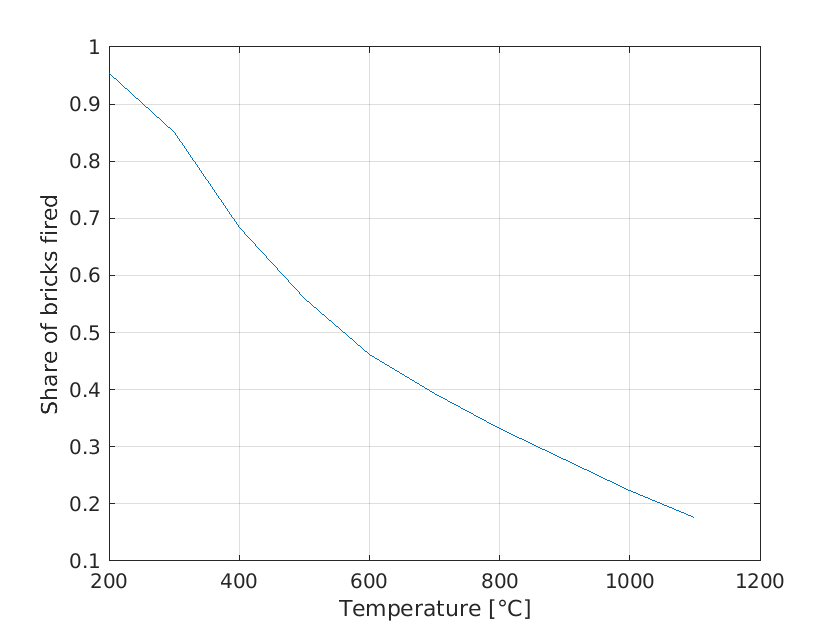

load("2401_longwide.mat")
% for i = 1:100
%     pdeplot3D(model,"ColorMapData", T(:,i));
%     timedispl = duration(seconds(tlist(i)),'format','hh:mm');
%     title(['Time: ', char(timedispl)])
%     caxis([T_min, T_max]);
%     F(i) = getframe(gcf);
%     drawnow
%     view([-0 90])
%     %path = "../figures/" + string(i) + ".jpg";
%     %saveas(gcf, path) 
% end
bins = [200, 300, 400, 500, 600, 700, 800, 900, 1000, 1100];
hist=[];
for i = bins
    lowT =find(T<i);
    soaking = T;
    soaking(lowT)=0;
    soaking=soaking~=0;
    soaking_period=sum(soaking, 2);
    sufficient_bricks=soaking_period~=0;
    sufficient_percent=sum(sufficient_bricks)/length(T);
    hist = [hist, sufficient_percent];
    
end
plot(bins, hist)
xlabel('Temperature [°C]')
ylabel('Share of bricks fired')

grid on

path1 = "Figures/100h_noconv/analysis.jpg";
%saveas(gcf, path1)
